# Task 1

disp ("Task 1")

Task 1


f = str2sym('1/(1 + x)');
tf = taylor(f);
pretty(tf)

$$-x^{5}+x^{4}-x^{3}+x^{2}-x+1$$

## Task 2

disp ("Task 2")

Task 2


syms y x;
f = str2sym('1/(x + y)');

disp ("Разложение по х")

Разложение по х


tf = taylor(f, x, 'Order', 7);
pretty(tf)

 2    3    4    5    6
x    x    x    x    x     x   1
-- - -- + -- - -- + -- - -- + -
 3    4    5    6    7    2   y
y    y    y    y    y    y




disp ("Разложение по y")

Разложение по y


tf = taylor(f, y, 'Order', 7);
pretty(tf)

 2    3    4    5    6
y    y    y    y    y     y   1
-- - -- + -- - -- + -- - -- + -
 3    4    5    6    7    2   x
x    x    x    x    x    x



## Task 3

disp("Task 3")

Task 3


syms x;
f = str2sym('x * sin(x)');
tf = taylor(f, x, 2, 'Order', 10);
pretty(tf)

                                    2          3 / cos(2)   sin(2) \          4 / cos(2)   sin(2) \
2 sin(2) + (cos(2) - sin(2)) (x - 2)  - (x - 2)  | ------ + ------ | - (x - 2)  | ------ - ------ |
                                                 \    3        2   /            \    6       12   /

            5 / cos(2)   sin(2) \          6 / cos(2)   sin(2) \          7 / cos(2)   sin(2) \
   + (x - 2)  | ------ + ------ | + (x - 2)  | ------ - ------ | - (x - 2)  | ------ + ------ |
              \   60       24   /            \   120      360  /            \  2520      720  /

            8 / cos(2)   sin(2) \          9 / cos(2)   sin(2) \
   - (x - 2)  | ------ - ------ | + (x - 2)  | ------ + ------ | + (2 cos(2) + sin(2)) (x - 2)
              \  5040     20160 /            \ 181440    40320 /



## Task 4

disp("Task 4")

syms k;
f = (-1)^k/k^2;
sum1 = symsum(f, k, 1, Inf) 

syms k x;
f = (-1)^(k) * x^(2 * k + 1) / factorial(2 * k + 1);
sum2 = symsum(f, k, 0, Inf)

## Task 5

disp("Task 5")

Task 5


syms n;
f = (1 / 2) * (1 - (1 / 3)^n);
l = limit(f, n, inf)

$$l = \frac{1}{2}$$

if (l == 0)
    disp("Ряд сходится")
else
    disp("Ряд расходится")
end

Ряд расходится


disp("Сумма:")

Сумма


symsum(f, n, 0, Inf)

$$ans = \infty$$

## Task 6

disp("Task 6")

Task 6


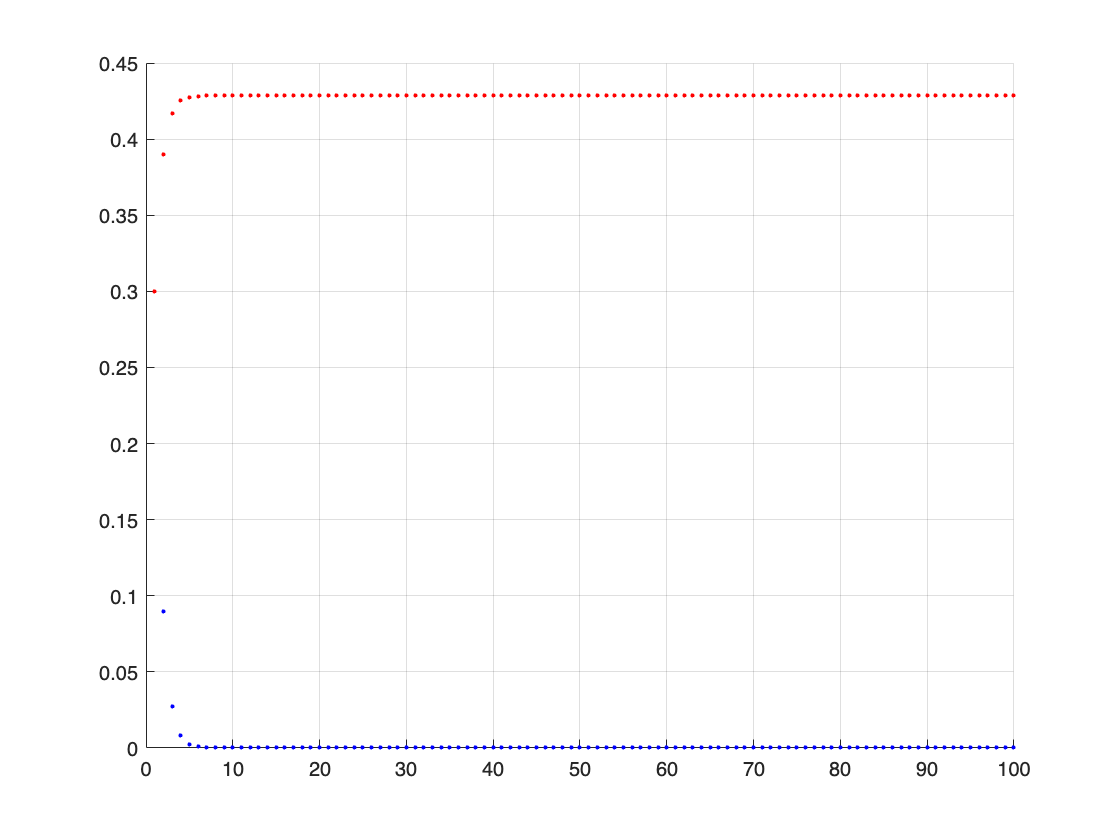

f1 = 0.4286

f1 = myFun(@(n) ((0.3).^n), 100)

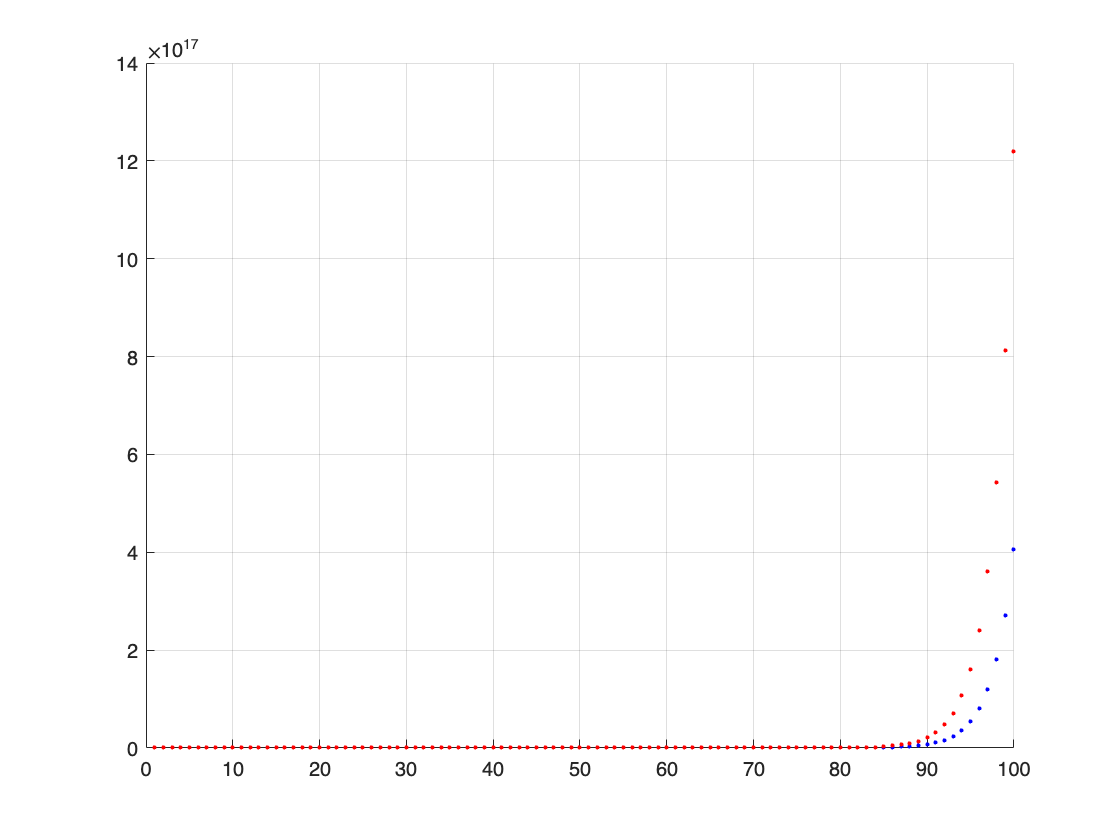

f2 = 1.2197e+18

f2 = myFun(@(n) ((1.5).^n), 100)

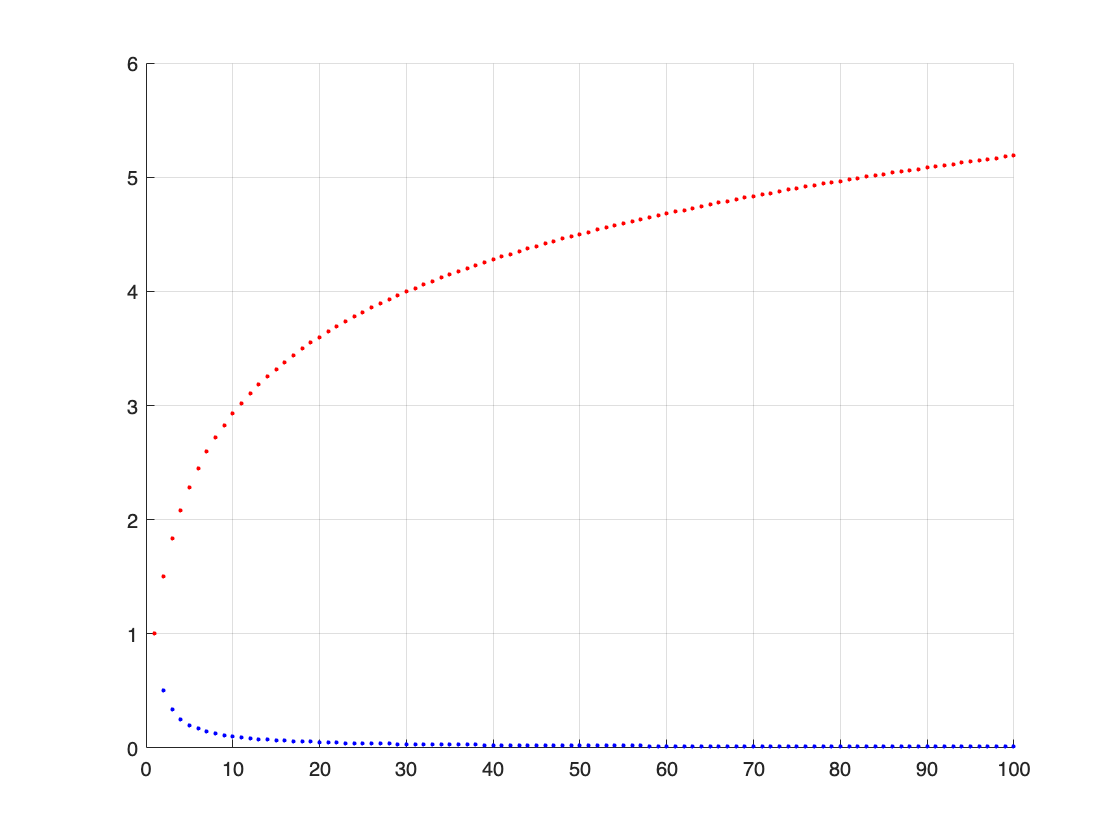

f3 = 5.1874

f3 = myFun(@(n) (1./n), 100)

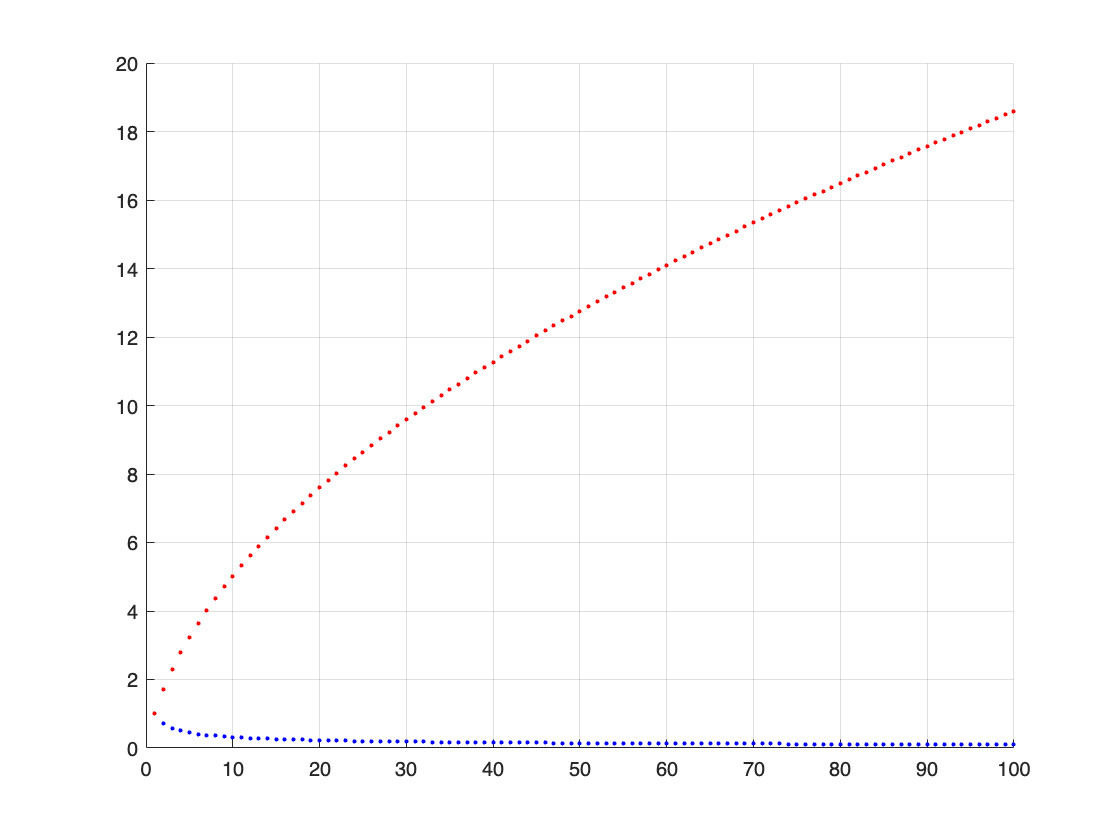

f4 = 18.5896

f4 = myFun(@(n) (1./sqrt(n)), 100)

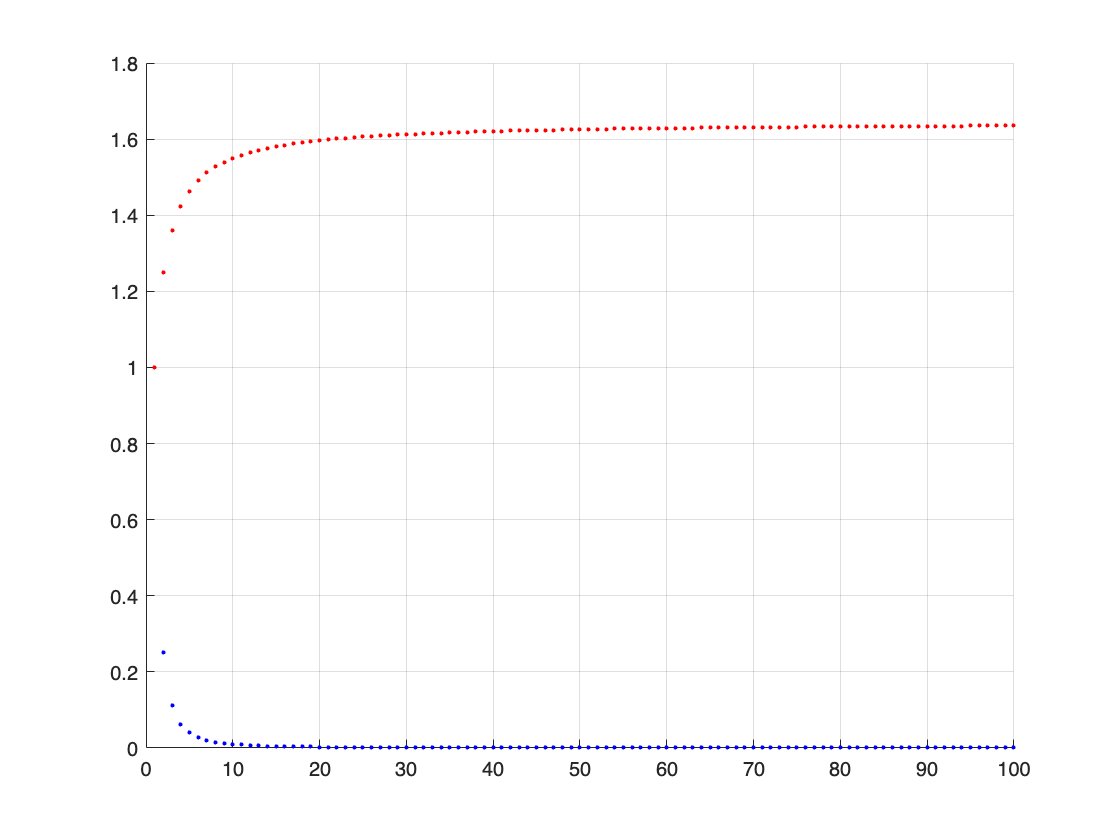

f5 = 1.6350

f5 = myFun(@(n) (1./(n.^2)), 100)

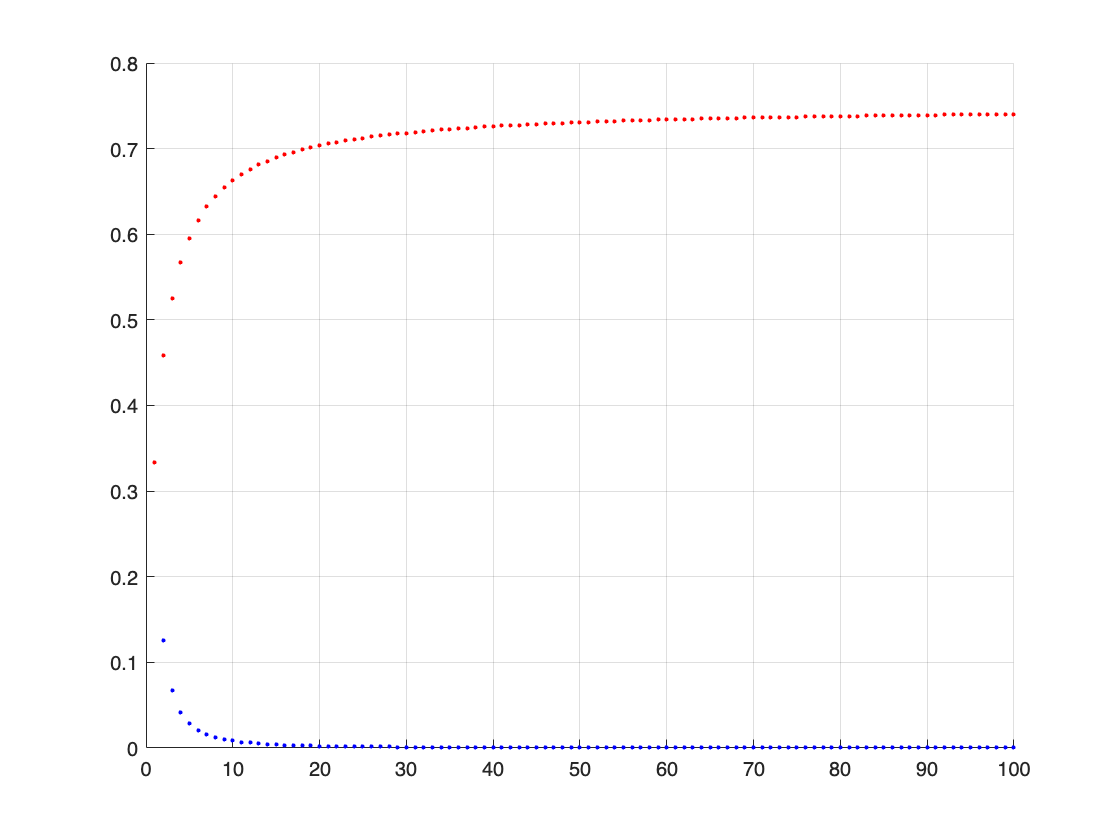

f6 = 0.7401

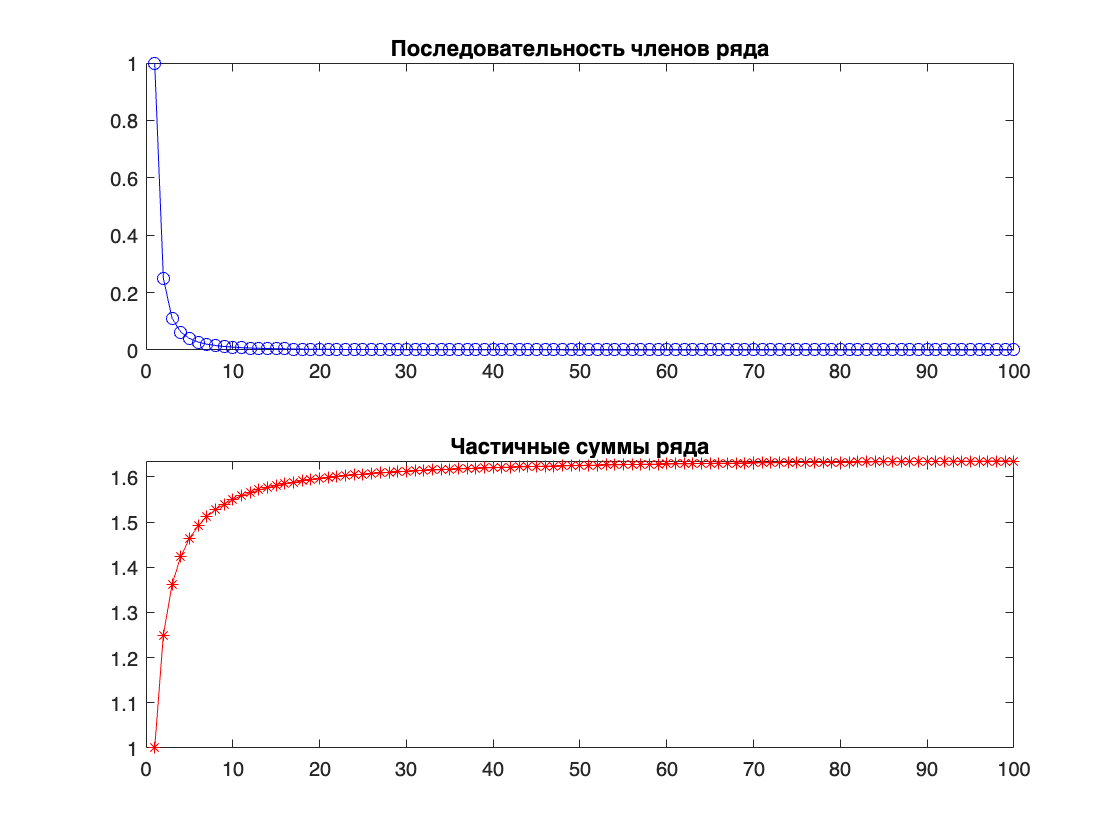

Значение суммы для 100 членов ряда: 1.6350


f6 = myFun(@(n) (1./(n.^2+2.*n)), 100)

function [sumvalue] = myFun(f,count)
    n = 1:count;
    figure;
    grid on;
    hold on;
    plot(n, f(n), '.', 'Color', 'b')
    sumvalue = 0;
    for i = 1:count
        sumvalue = sumvalue + f(i);
        plot(i, sumvalue,'.', 'Color', 'r')
    end
end